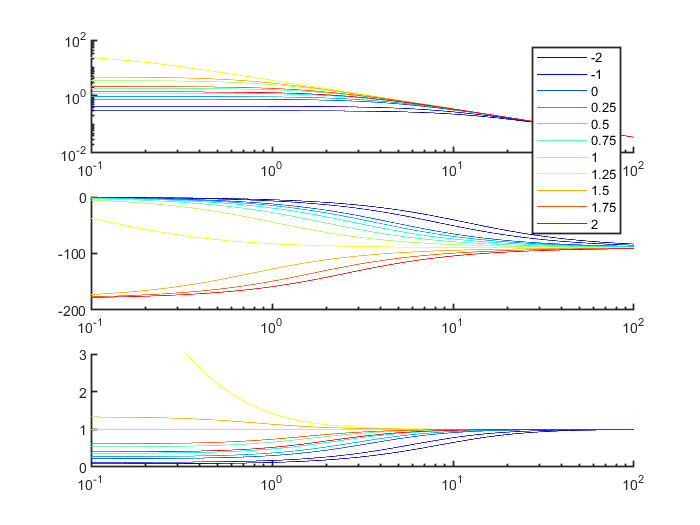

clear ; close all ; clc

syms s

% gamma = [-10 -5 -3 -1 0 0.25 0.5 0.75 1 1.4485 2]';
gamma = [-2:1:0 0.25:0.25:2]';
% gamma = [1.25:0.05:1.45]';
full_gain = gamma + -1;
% gamma = 0;
% gamma = 0;
n_gamma = length(gamma);

tau = 0.155;
G = tf(3.5, [tau 1]);
% G.IOdelay = 0.02;
% G = pade(G, 1)
% H = minreal(G / (1 - G*(-1 + gamma)))
% fv = (0.01:100)';
fv = logspace(-1,2, 1000)';
wv = fv*2*pi;
nf = length(fv);
Gain = nan(nf, n_gamma);
Phase = nan(nf, n_gamma);
Error = nan(nf, n_gamma);
for n = 1:n_gamma
    H(n).main = minreal(G / (1 - G*(-1 + gamma(n))));
    [gain,phase] = bode(H(n).main, wv);
    Gain(:,n) = squeeze(gain);
    Phase(:,n) = squeeze(phase);
    
    E(n).main = minreal(1 + H(n).main*(-1 + gamma(n)));
    [gain,~] = bode(E(n).main, wv);
    EGain(:,n) = squeeze(gain);
end

fig = figure (1); clf
set(fig, 'Color', 'w')
ax(1) = subplot(3,1,1); cla ; hold on ; %ylim([0 3])
    h.gain = plot(fv, Gain);

ax(2) = subplot(3,1,2); cla ; hold on ; %ylim([-90 20])
    h.phase = plot(fv, Phase - 0*360);
    
ax(3) = subplot(3,1,3); cla ; hold on ; ylim([0 3])
    h.error = plot(fv, EGain);
    
legend(h.gain, string(gamma))

set(ax, 'Color', 'none', 'LineWidth', 1, 'XScale', 'log')
set(ax(1), 'yScale', 'log')

cc = jet(n_gamma);
set(h.gain, {'Color'}, num2cell(cc,2))
set(h.phase, {'Color'}, num2cell(cc,2))
set(h.error, {'Color'}, num2cell(cc,2))

clear ; close all ; clc
syms s K_p tau gamma t_d

% K_p = 4;
% tau = 0.1592;
% t_d = 0.02;

PadeA = (1 - (t_d/2)*s)  / (1 + (t_d/2)*s)

$$PadeA = -\frac{\frac{s\,t_{d}}{2}-1}{\frac{s\,t_{d}}{2}+1}$$


P = 1 / (tau*s + 1);
C = K_p;
G = P*C

$$G = \frac{K_{p}}{s\,\tau +1}$$

H = G / (1 - G*(-1 + gamma));
H = collect(H,s)

$$H = \frac{K_{p}}{\tau \,s+K_{p}-K_{p}\,\gamma +1}$$


[N,D] = numden(H)

$$N = K_{p}$$

$$D = K_{p}-K_{p}\,\gamma +s\,\tau +1$$


char_eq = D == 0

$$char\_eq = K_{p}-K_{p}\,\gamma +s\,\tau +1=0$$

Z = solve(char_eq, s)

$$Z = -\frac{K_{p}-K_{p}\,\gamma +1}{\tau }$$

gamma_crit = solve(Z(1)==0, gamma)

$$gamma\_crit = \frac{K_{p}+1}{K_{p}}$$

syms L
Hm = subs(H, gamma, 0)

$$Hm = \frac{K_{p}}{K_{p}+s\,\tau +1}$$

Hn = subs(H, K_p, K_p*L)

$$Hn = \frac{K_{p}\,L}{s\,\tau +K_{p}\,L-K_{p}\,L\,\gamma +1}$$


eq = Hm == Hn

$$eq = \frac{K_{p}}{K_{p}+s\,\tau +1}=\frac{K_{p}\,L}{s\,\tau +K_{p}\,L-K_{p}\,L\,\gamma +1}$$

Ln = solve(eq, L)

$$Ln = \frac{s\,\tau +1}{K_{p}\,\gamma +s\,\tau +1}$$


K_p_num = 4;
tau_num = 0.1592;
t_d_num = 0.02;

gamma_num = [0 -3 -1 0.5 0.75 1];
n_gamma = length(gamma_num);

n_freq = 200;
fv = logspace(-1, 2, n_freq)';
wv = 2*pi*fv;
Ln_tf = tf();
Gain = nan(n_freq, n_gamma);
Phase = nan(n_freq, n_gamma);
for g = 1:n_gamma
    Ln_num = subs(Ln, [K_p, tau, t_d gamma], ...
        [K_p_num tau_num t_d_num gamma_num(g)]);
    Ln_tf(g) = minreal(sym2tf(Ln_num));
    [gain,phase] = bode(Ln_tf(g), wv);
    Gain(:,g) = squeeze(gain);
    Phase(:,g)  = squeeze(phase);
    
%     Hn_num = subs(Hn, [K_p, tau, t_d gamma L], ...
%         [K_p_num tau_num t_d_num gamma_num(g) Ln_num]);
%     Hn_tf = minreal(sym2tf(Hn_num))
%     Hm_num  = subs(Hm, [K_p, tau, t_d], [K_p_num tau_num t_d_num]);
%     Hm_tf = minreal(sym2tf(Hn_num))
end


fig = figure (1) ; clf
set(fig, 'Color', 'w', 'Units', 'inches', 'Position', 1*[2 2 4 7], 'Visible', 'on')
clear ax h

ax(1,1) = subplot(2,1,1); cla ; hold on ; ylabel('Gain')
    h.gain = plot(fv, Gain, 'LineWidth', 1);
   
ax(2,1) = subplot(2,1,2); cla ; hold on ; ylabel('Phase (°)')
    h.phase = plot(fv, Phase, 'LineWidth', 1);

xlabel('Frequency (hz)')
set(ax, 'Color', 'none', 'LineWidth', 1, 'XScale', 'log', 'Box', 'on', 'FontSize', 8)
set(ax,  'XGrid', 'on', 'YGrid', 'on')
set(ax(1), 'YScale', 'log')

set(ax(1), 'YLim', [0.1 1.1], 'YTick', 0:0.1:2)
set(ax(2), 'YLim', [-270 90], 'YTick', -360:90:360)

cc = hsv(n_gamma);
set(h.gain, {'Color'}, num2cell(cc,2))
set(h.phase, {'Color'}, num2cell(cc,2))
legend(h.gain, "\gamma = " + string(gamma_num), 'Box', 'off')
    

syms L
Hm = subs(H, gamma, 0)

$$Hm = \frac{K_{p}}{K_{p}+s\,\tau +1}$$

Hn = subs(H, K_p, K_p*L)

$$Hn = \frac{K_{p}\,L}{s\,\tau +K_{p}\,L-K_{p}\,L\,\gamma +1}$$


eq = (1 + Hm*-1) == (1 + Hn*(-1 + gamma))

$$eq = 1-\frac{K_{p}}{K_{p}+s\,\tau +1}=\frac{K_{p}\,L\,\left(\gamma -1\right)}{s\,\tau +K_{p}\,L-K_{p}\,L\,\gamma +1}+1$$

Ln = solve(eq, L)

$$Ln = -\frac{1}{\gamma -1}$$


syms G L

HmE = 1 + (G / (1 + G))

$$HmE = \frac{G}{G+1}+1$$

HnE = 1 + (L*G / (1 - L*G*(-1 + gamma)))*(-1 + gamma)

$$HnE = 1-\frac{G\,L\,\left(\gamma -1\right)}{G\,L\,\left(\gamma -1\right)-1}$$


eq = HmE == HnE

$$eq = \frac{G}{G+1}+1=1-\frac{G\,L\,\left(\gamma -1\right)}{G\,L\,\left(\gamma -1\right)-1}$$

test = solve(eq, L);
simplify(test)

$$ans = \frac{1}{\left(2\,G+1\right)\,\left(\gamma -1\right)}$$


test = subs(test, G, K_p/(tau*s+1))

$$test = \frac{1}{\gamma -\frac{2\,K_{p}}{s\,\tau +1}+\frac{2\,K_{p}\,\gamma }{s\,\tau +1}-1}$$

simplify(test)

$$ans = \frac{s\,\tau +1}{\left(\gamma -1\right)\,\left(2\,K_{p}+s\,\tau +1\right)}$$